# Getting Started with the ELARA Toolbox

**Welcome to the ELARA toolbox!**

This script will introduce you to the most important functionality of the toolbox for simulating the dynamics of rigid-flexible systems.

## Installation

To check if the installation was successful, you can run

elara.setup;

Verifying ELARA toolbox installation...
  [PASS]  Core toolbox installed correctly.
  [PASS]  Compiled MEX files found under elara.mex.
  [PASS]  CasADi installation found.


To improve the performance of the simulations, you can use MATLAB coder to build mex files of important functions. First ensure an appropriate compiler is configured using

% mex -setup C++

The mex files can then be build using

% elara.build;

After the mex files are compiled successfully, they will be automatically used by the toolbox.

For optimal control, install CasADi from the [CasADi website](https://web.casadi.org/) and add it to the MATLAB path.

## **Defining a System**

The first step is defining the system we want simulate. For this, ELARA provides two classes to specify the different link types:

- `elara.RigidLink` to define a rigid body

- `elara.FlexibleLink` to define a flexible link, which is modeled as a geometrically exact (Cosserat) beam.

Each link is connected to its predecessor (or the fixed base) via a one-DOF screw joint, e.g., a revolute or a prismatic joint. Moreover, it is possible to specify cantilever beams, which are directly fixed to the base without any moving joint. This is the case for the system we will simulate here.

Both classes are child classes of `elara.abstract.Link`, and can be directly assembled together into a heterogeneous array.

There are several example systems already implemented. Here, we will use an example system that consist of a flexible cantilever link, to which two rigid bodies are attached via revolute joints:

links = systemDef_cantilever_system();

The function directly returns a link array, where each element is one of the two link types we introduced earlier.

## Setting up the Simulation

To use the specified links in a simulation, you will need to generate a `elara.Simulation `object by passing the links to the constructor:

simulation = elara.Simulation(links, "displayInfo",false)

simulation =   Simulation with properties:

          Name: ""
    integrator: [1×1 elara.integration.VIBroyden]
         links: [3×1 elara.abstract.Link]
        system: [1×1 elara.SystemNum]
    parameters: [1×1 elara.SimulationParameters]
       results: [1×1 elara.SimulationResults]


In this step, the individual links are assembled into a complete multibody system, which contains all information and properties of the system required for simulations or optimal control applications.

This multibody system is stored in the `system` property of the `simulation `object`:`

system = simulation.system

system =   SystemNum with properties:

                  frames: [1×1 elara.FramePropertiesNum]
                    cSys: [17×1 double]
                    dSys: [17×1 double]
                    qRef: [17×1 double]
            isCantilever: 1
                      g0: [4×4 double]
     LinkAdjacencyMatrix: [3×3 double]
    FrameAdjacencyMatrix: [7×7 double]
                  nLinks: 3
                 nJoints: 2
                 nFrames: 7
                    nDoF: 17
                 nInputs: 2
        linkFrameIndices: [2×3 uint16]
           indexTCPFrame: 0
                 g_B_TCP: [4×4 double]


We can adjust various properties of the system after it has been created. Here, we will change the simulation name and the orientation of the first link by specifying an appropiate SE3 transformation matrix:

% Construct rotation matrix
RRef0 = [
    0  0 1
    0  1 0
    -1 0 0
    ];

% Set pose of the first link via homogeneous transformation matrix (optional)
simulation.system.g0 = elara.SE3.matrix(RRef0, zeros(3,1));

% Name of the simulation (optional)
simulation.Name = "My first simulation";

We can now easily visualize the system using the built-in visualization methods:

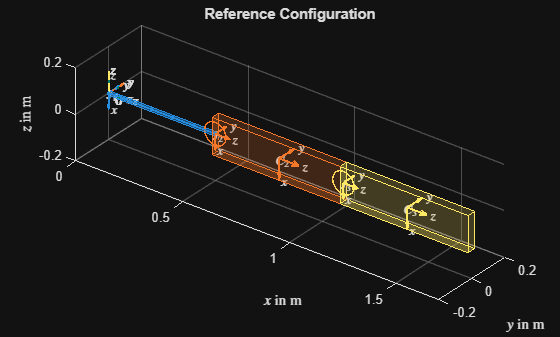

% Visualization of the system in its reference configuration
% (i.e., for q = 0)
simulation.visualizeSystemRefConf;
xlim([0,1.7]);
ylim([-0.2,0.2]);
zlim([-0.2,0.2]);

### Specifying Simulation Parameters

To perform a simulation, we have to specify various parameters, such as the duration (end time) of the simulation, the initial configuration and velocity, and others. These are set in the `simulation.parameters` property.

% End time
simulation.parameters.tEnd = 5;

The initial configuration is specified via the initial values of the system's generalized coordinates. For the present system, these are the discrete deformations of the beam segments, and the two joint angles of the revolute joints.

The initial configuration could be easily initialized as zero so that the simulation starts in the system's reference configuration:

simulation.parameters.q0 = zeros(simulation.system.nDoF, 1);

We can also specify non-zero initial configurations; for example, we can set the joint angles to certain values:

q0 = simulation.system.setJointAngles(deg2rad([-30,90]));
simulation.parameters.q0 = q0;

The initial velocity is specified analogously. Here, we want to start the system in zero velocity:

simulation.parameters.qDot0 = zeros(simulation.system.nDoF,1);

To get a better idea of the used initial configuration, we can easily visualize the system in this configuration:

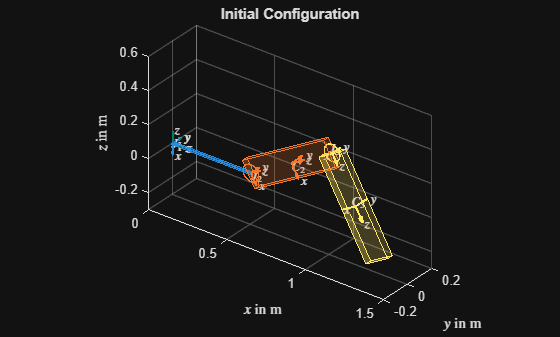

simulation.visualizeSystemConfig(simulation.parameters.q0);
xlim([0,1.5]);
ylim([-0.2,0.2]);
zlim([-0.3,0.6]);
title("Initial Configuration");

### Setting up the Integrator

Next, we must specify the integration method used for the simulation. The type and parameters of the integrator can be set using the `simulation.integrator` property.

Here, we will use the Lie-group variational integrator (LGVI), which is highly efficient for many systems; especially if they contain flexible links.

simulation.integrator = elara.integration.VIBroyden;

Next, we have to set certain parameters for the solver. The main parameter, which defines the accuracy of the simulation, is the integration time step $h$:

simulation.integrator.h = 2^-10;

Additionally, we will use a first-order dissipation term for increased computational efficiency:

simulation.integrator.useFirstOrderDissipation = true;

There are several additional parameters for the LGVI that can be used to fine-tune its performance and robustness; here, we will leave them at their default values. See the documentation for details.

## Running the Simulation

If all parameters are set, you can then start the simulation. By default, the solver will display certain metadata and statistics:

simulation = simulation.simulateSystem;

Starting integration (varint-broyden)...
   Total integration time (tictoc):     0.375439 s
   Simulation end time:                 5.000 s
   Number of successful time steps:     5121
   Time step:                           9.766e-04 s = 2^-10.00 s
   Approx. comp. time per step:         7.331e-05 s
   Iteration Count (Avg/Min/Max/Total): 3.1436 / 2 / 6 / 16095
   Residual (Avg/Min/Max):              2.931e-09 / 7.927e-13 / 9.981e-09
   Target solver error violations:      0 (0.00% of overall steps)


The raw numerical results of the simulation are then available as an `elara.SimulationResults` object at:

simulation.results

ans =   SimulationResults with properties:

                 eta: [6×7×5121 double]
                   g: [4×4×7×5121 double]
                   q: [17×5121 double]
               q_dot: [17×5121 double]
                tout: [5121×1 double]
       kineticEnergy: [0×1 double]
     potentialEnergy: [0×1 double]
        strainEnergy: [0×1 double]
         totalEnergy: [0×1 double]
    solverIterations: [2 2 2 3 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 3 2 2 2 2 2 2 2 2 3 2 2 2 3 2 2 3 2 2 3 2 3 2 3 2 3 2 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 4 4 4 4 4 … ] (1×5121 double)
      solverResidual: [5.3697e-09 7.4937e-09 1.4713e-09 1.4571e-11 4.4302e-09 1.0926e-09 2.5384e-09 1.0478e-10 2.1953e-10 8.2432e-10 1.1525e-09 2.6655e-09 3.0784e-09 3.9154e-09 3.9137e-09 5.1657e-09 5.7480e-09 7.4193e-09 8.3410e-09 … ] (1×5121 double)
      solverExitFlag: [0 0 0

## Post-Processing and Plotting

After the simulation has finished, we can use the built-in plotting and visualization tools to inspect the results.

### Generating Plots

For example, we can generate certain plots with:

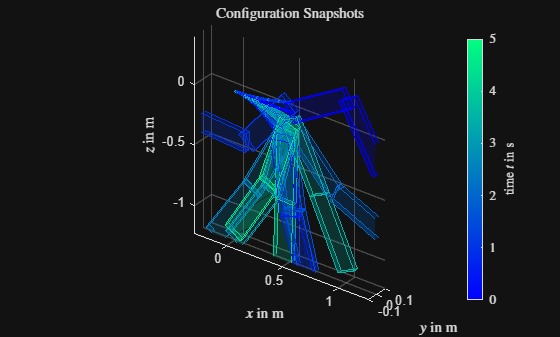

% Snapshots of the simulation results
simulation.drawSnapshots("nSnapShots", 10);

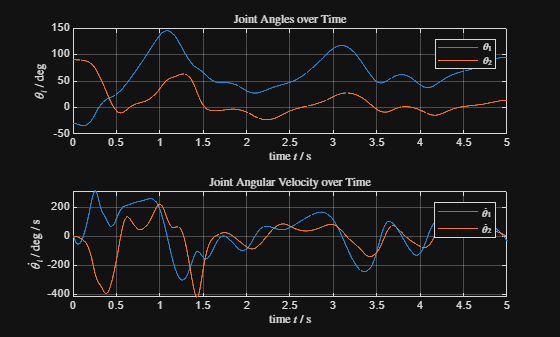

% Joint angles over time
simulation.plotJointAngles;

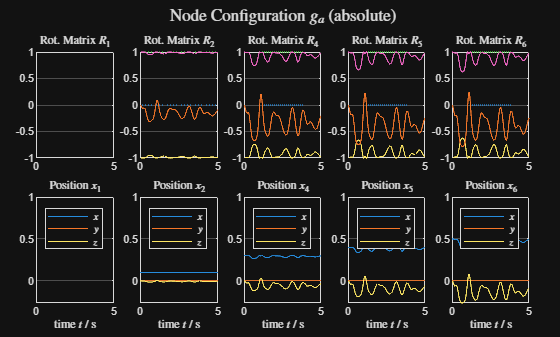

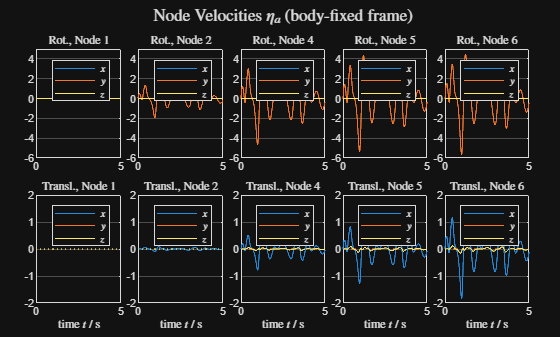

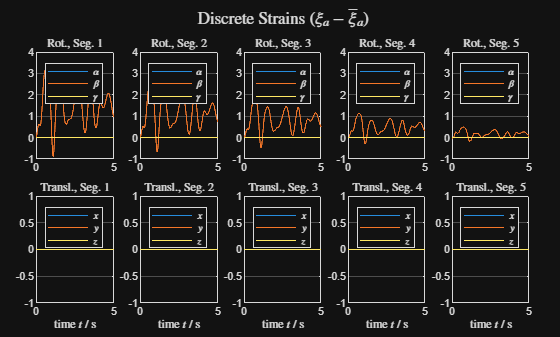

% Configurations, velocities, and discrete deformations of the cantilever beam
simulation.plotBeamData;

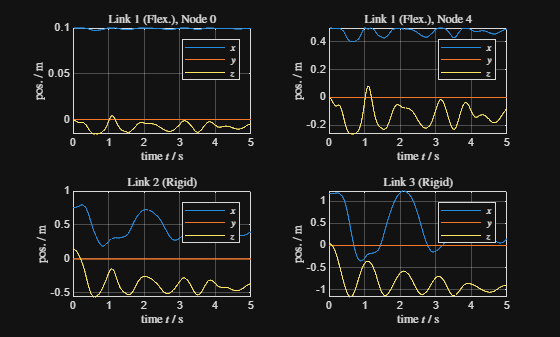

% Absolute positions of certain system frames (including the cross-section
% frames of the cantilever beam and the reference frames of the rigid
% bodies)
simulation.plotFramePositions;

% You can also generate all available plots at once with
% simulation.plotAll;

### Animating the Simulation Results

Finally, we can animate the completed simulation by running:

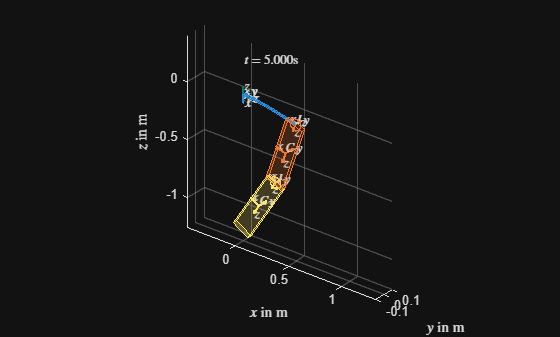

simulation.animateSimResults("figureName", "Animation Getting Started Guide");

## Detailed Example Scripts

To learn more about the capabilities of the toolbox, you can run and inspect the various example scripts that are included in the toolbox in the /`examples` folder.

For dynamical simulation, the included examples are:

% simulation_continuum_manipulator
% simulation_rigid_flexible_system
% simulation_rigid_robot
% simulation_rigid_flexible_robot_PD_control
% simulation_chiemsee_lecture_notes

Many of these demonstrate the numerical advantages gained by using the Lie-group variational integrator compared to standard ODE solvers.

### Optimal Control Examples

Additionally, there are several examples that demonstrate the use of ELARA for optimal control applications. To run these examples, CasADi is required.

The implemented examples are:

% optimal_control_planar_robot
% optimal_control_rigid_robot
% optimal_control_continuum_manipulator